# Trilateration Using Transmitters and Receivers

[Jerry Landivar G.](https://www.linkedin.com/in/jerry-land%C3%ADvar-guartatanga-0812b8231/), [Carolina Ormaza C.](https://www.linkedin.com/in/carolina-elizabeth-ormaza-castillo-789487212/), [Verónica Ojeda C.](https://www.fiec.espol.edu.ec/es/cv/ojeda-carrera-ver%C3%B3nica-jacqueline), [Víctor Asanza](https://orcid.org/0000-0002-2786-4162), [Juan Carlos Aviles](https://www.fiec.espol.edu.ec/es/cv/avil%C3%A9s-castillo-juan-carlos)

- Main Code: [https://github.com/vasanza/WiFi_RSSI_Localization](https://github.com/vasanza/WiFi_RSSI_Localization)

- `SRC: `[https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- `DataPort: `[https://dx.doi.org/10.21227/x6jw-m015](https://dx.doi.org/10.21227/x6jw-m015)

- `Reference: `

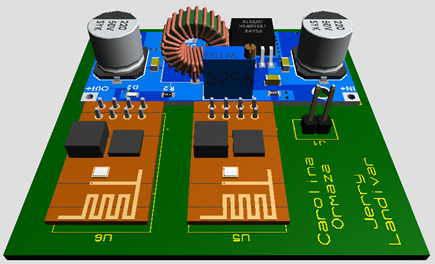

# 1- Load Raw Data

clear;clc;%clear all
%Prepare the raw dataset
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder
filenames = FindCSV(datapath);%List All CSV files
allData=[];
for i=1:length(filenames)% Through all files
    data=readtable(fullfile(datapath,filenames(i).name));%Select i CSV file
    data=[data(2:size(data,1),1:3) data(2:size(data,1),5:104)];
    dataNew=table2array(data);% Array Double
    dataNew(isnan(dataNew)) = 0;%Remove NAN numbers
    for j=1:3:length(dataNew)-2
       AP0=dataNew(j,4:103);
       AP1=dataNew(j+1,4:103);
       AP2=dataNew(j+2,4:103);
       Q=dataNew(j,1)*ones([1,length(AP0)]);
       x=dataNew(j,2)*ones([1,length(AP0)]);
       y=dataNew(j,3)*ones([1,length(AP0)]);
       DataColum=[Q' x' y' AP0' AP1' AP2'];
       allData=[allData;DataColum];
    end
end
%Example
%Cuadricula, X, Y, AP0, AP1, Ap2
%1,10,190,56,-74,-69
%.
%.
%%1,10,190,21,-25,-32

clear data dataNew i AP0 AP1 AP2 Q x y j DataColum 

# 2- Plot Raw Data (Dataset)

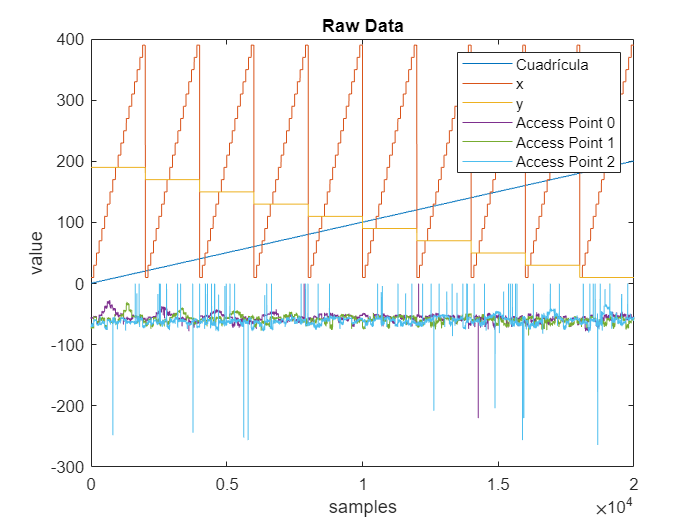

figure
plot(allData(:,:));title('Raw Data');xlabel('samples');ylabel('value');
%Cuadrícula; x; y; Access Point 0; Access Point 1; Access Point 2
legend('Cuadrícula', 'x', 'y', 'Access Point 0', 'Access Point 1', 'Access Point 2');

clear legend filenames datapath

# 2- Preprocessing Raw Data (Filtering and Normalization)

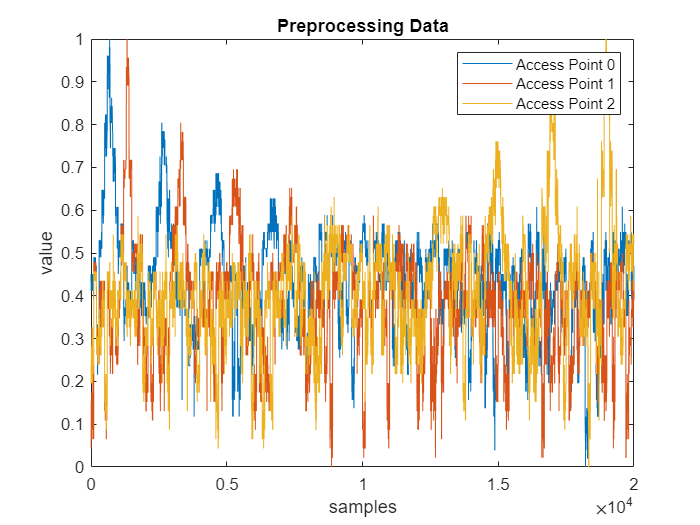

InputData=[];
for i=1:100:size(allData(:,4:6),1)-99
    InputData = [InputData; [hampel(allData(i:i+99,4)) hampel(allData(i:i+99,5)) hampel(allData(i:i+99,6))]];
end
DeNormMax=max(InputData(:,:));
DeNormMin=min(InputData(:,:));
InputDataNorm = fNormalization(InputData(:,:));%Normalization
% Access Point 0; Access Point 1; Access Point 2
Output = allData(:,1:3);%Cuadrícula; x; y;
plot(InputDataNorm(:,:));title('Preprocessing Data');xlabel('samples');ylabel('value');
legend('Access Point 0', 'Access Point 1', 'Access Point 2');

clear DataColum i allData

# [4] - Feature Extraction (RRSI measurements have already been averaged)

%Prepare the raw dataset
allDataMean=[];x=[];y=[];
for i=1:100:size(InputDataNorm,1)-99
    DataMean = mean(InputDataNorm(i:i+99,:));
    %DataMean = mean(InputData(i:i+99,:));
    allDataMean=[allDataMean;DataMean];
    x=[x;Output(i,2)];
    y=[y;Output(i,3)];
end

figure
subplot(3,1,1);AP=0;
z=allDataMean(:,AP+1);
scatter(x,y,30,z,'filled');
title('Mean RSSI Access Point 0');xlabel('X Position');zlabel('Mean RSSI');ylabel('Y Position');
colorbar()
subplot(3,1,2);AP=1;
z=allDataMean(:,AP+1);
scatter(x,y,30,z,'filled');
title('Mean RSSI Access Point 1');xlabel('X Position');zlabel('Mean RSSI');ylabel('Y Position');
colorbar()
subplot(3,1,3);AP=2;
z=allDataMean(:,AP+1);
scatter(x,y,30,z,'filled');
title('Mean RSSI Access Point 2');xlabel('X Position');zlabel('Mean RSSI');ylabel('Y Position');
colorbar()
clear i NewFeaturesLabels DataMean AP x y z

# 5- Statital Features Information

%'Mean RSSI Access Point 0'
AP0s = datastats(allDataMean(:,1))

AP0s = struct with fields:
       num: 200
       max: 0.9412
       min: 0.0771
      mean: 0.4394
    median: 0.4403
     range: 0.8641
       std: 0.1157


%'Mean RSSI Access Point 1'
AP1s = datastats(allDataMean(:,2))

AP1s = struct with fields:
       num: 200
       max: 0.9185
       min: 0.0800
      mean: 0.3800
    median: 0.3909
     range: 0.8385
       std: 0.1268


%'Mean RSSI Access Point 3'
AP2s = datastats(allDataMean(:,3))

AP2s = struct with fields:
       num: 200
       max: 0.9504
       min: 0.1278
      mean: 0.4095
    median: 0.3991
     range: 0.8226
       std: 0.1308


clear AP0s AP1s AP2s

# 6 - Feature Selection (Please set the maximum correlation value allowed.)

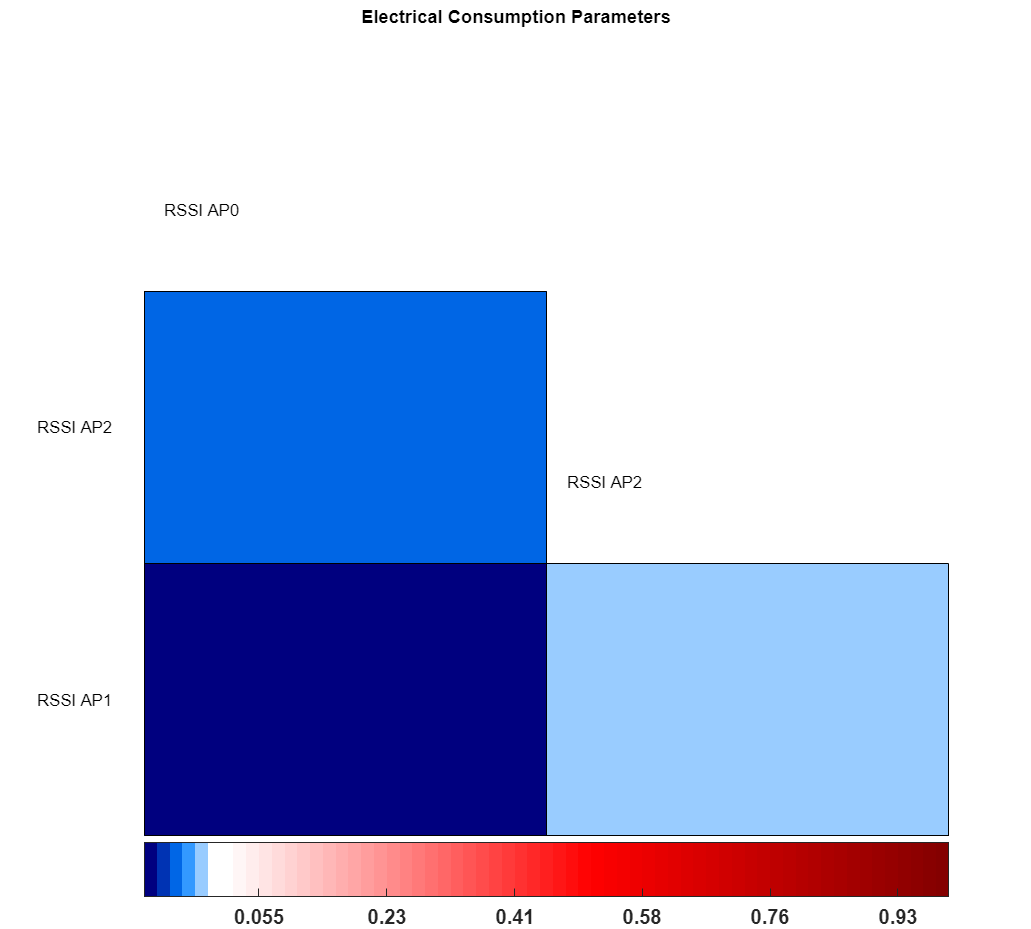

threshold = 0.75;%75<-------Maximum correlation value allowed
% Labels
FeaturesLabels = {'RSSI AP0','RSSI AP1','RSSI AP2'};
[NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(InputDataNorm,FeaturesLabels,threshold);

LabelsRemove(:)


ans =

  0×1 empty cell array



clear threshold LabelsRemove ans allFeatureNorm FeaturesLabels NewFeaturesLabels

# 8 - Regression Learner (Input output Data)

training_size=0.85; %85 (Training and testing), 15% Validation

% ---------------inputs: All previously selected features------------------
input_train=NewDataFeatures(1:round(size(NewDataFeatures,1)*training_size)-1,:)

% ----------------output: Energy in the next time step---------------------
output_train_x=Output(1:round(size(Output,1)*training_size)-1,2);%cloumn 2 is x
output_train_y=Output(1:round(size(Output,1)*training_size)-1,3);%column 3 is y

regressionLearner
clear allDataMean InputDataNorm InputData

# RMSE (Validation): 

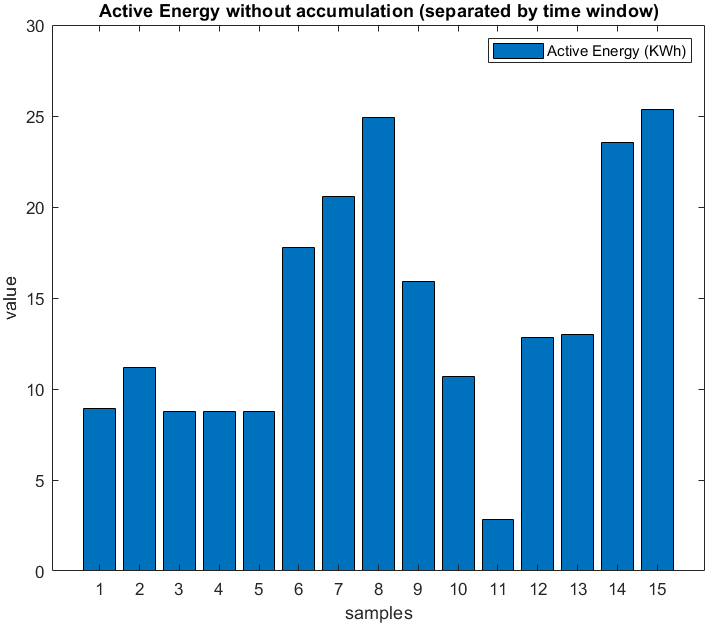

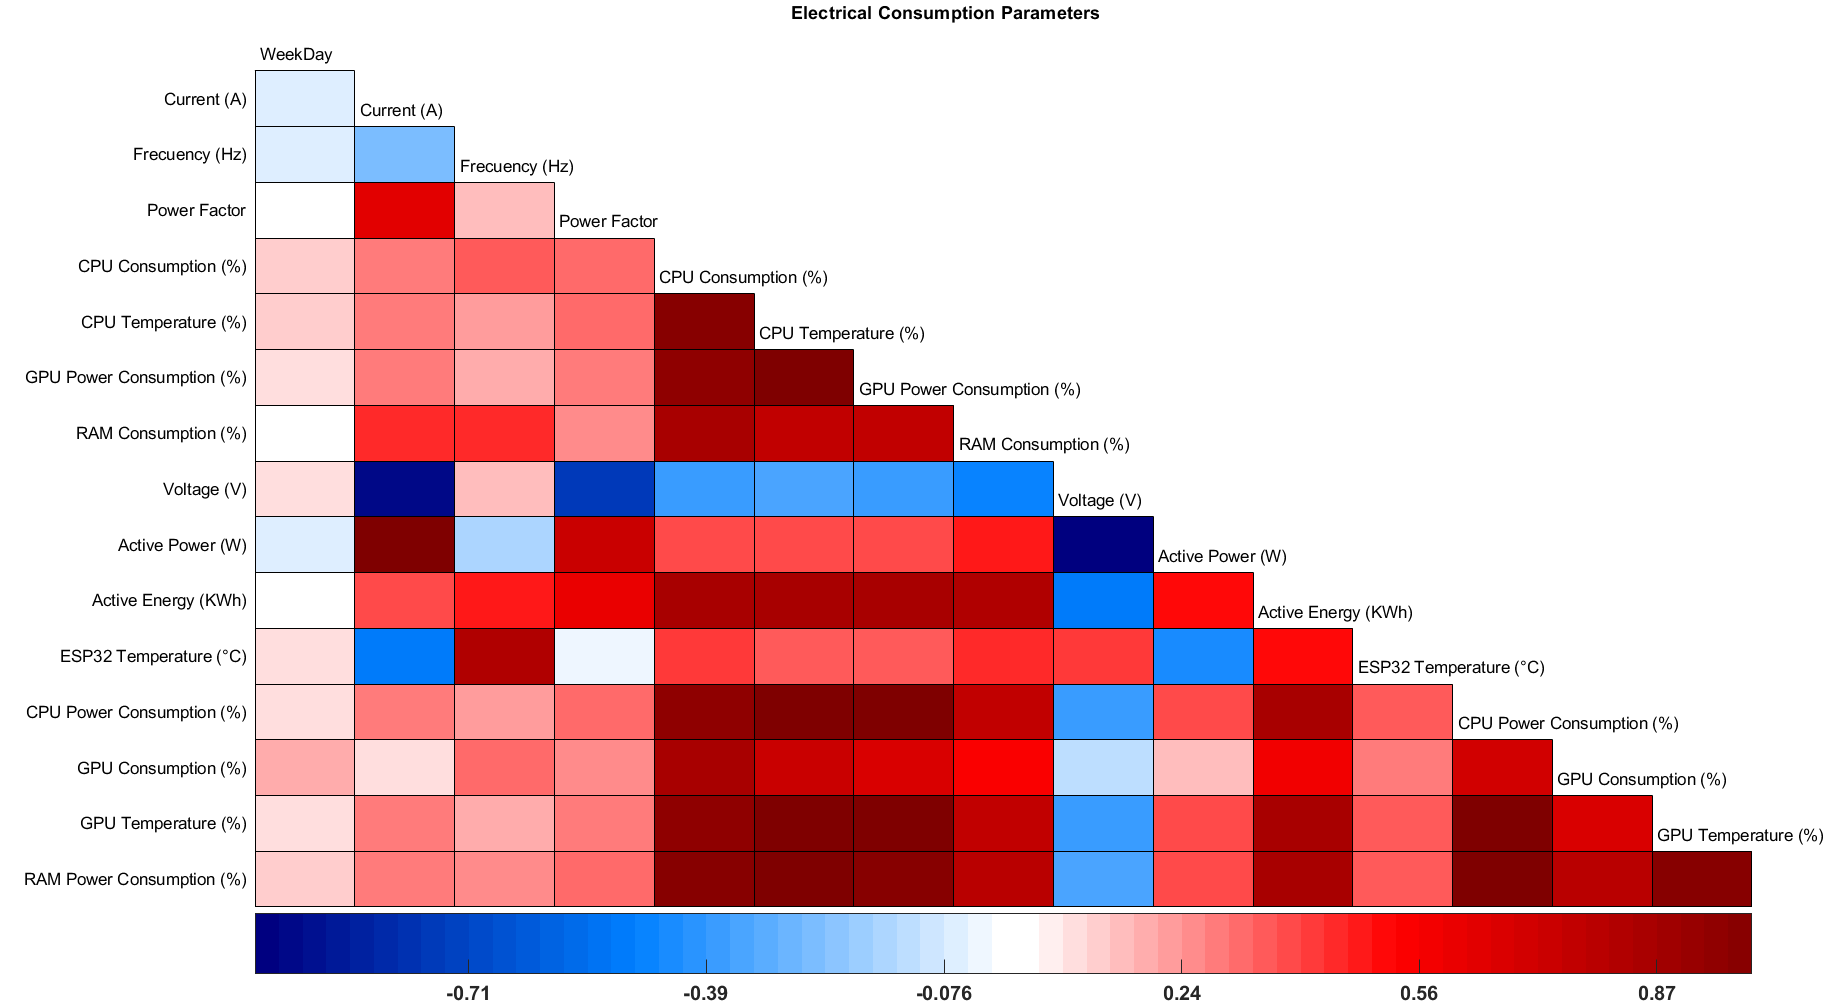

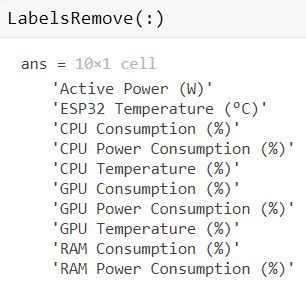

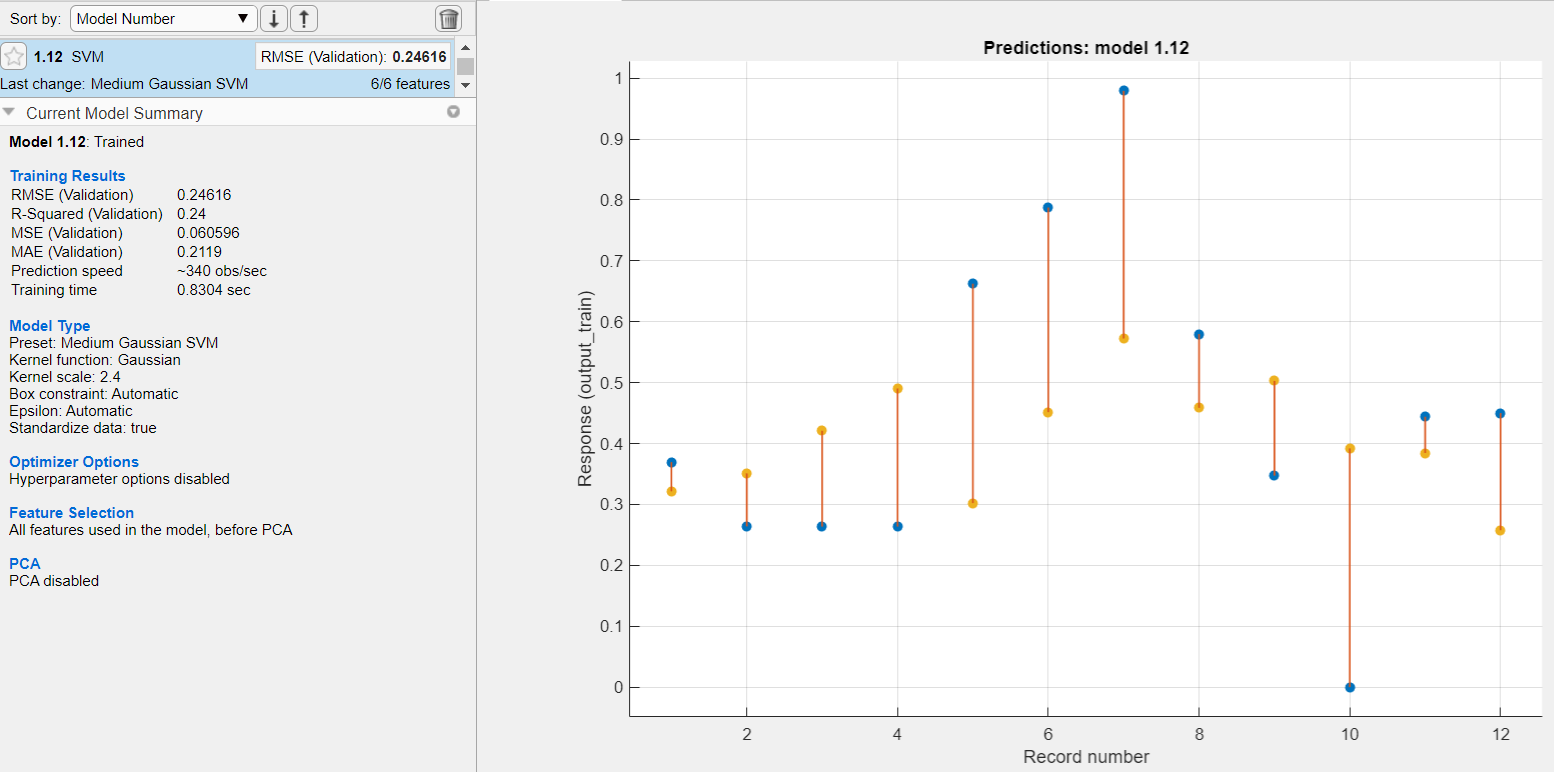

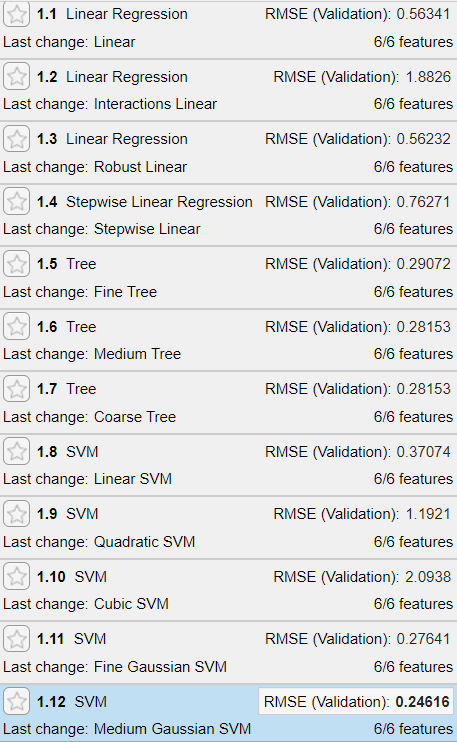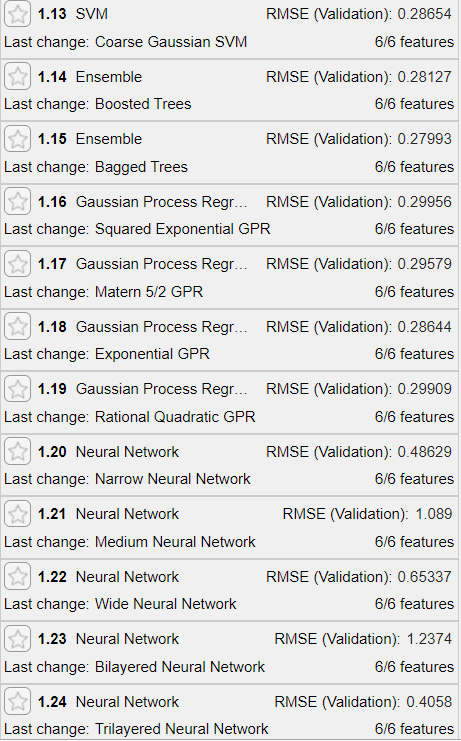

# RMSE (Testing): 1 month [threshold = 0.750;training_size=0.85;]

training_size=0.40;
% input: Energy
input_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size):size(NewDataFeatures,1)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size)+1:size(NewDataFeatures,1)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
[model_month, RMSE_month] = trainRegressionModel_month(input_train, output_train);
RMSE_month

RMSE_month = 0.9105

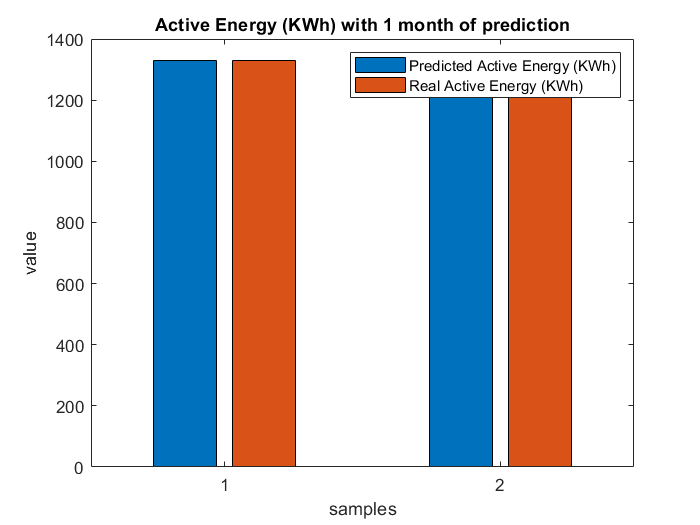

estimate_month=model_month.predictFcn(input_val);
estimate_month=fDenormalize(estimate_month,AEds.max,AEds.min);
output_month=fDenormalize(output_val,AEds.max,AEds.min);
figure; bar([estimate_month,output_month]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 month of prediction');

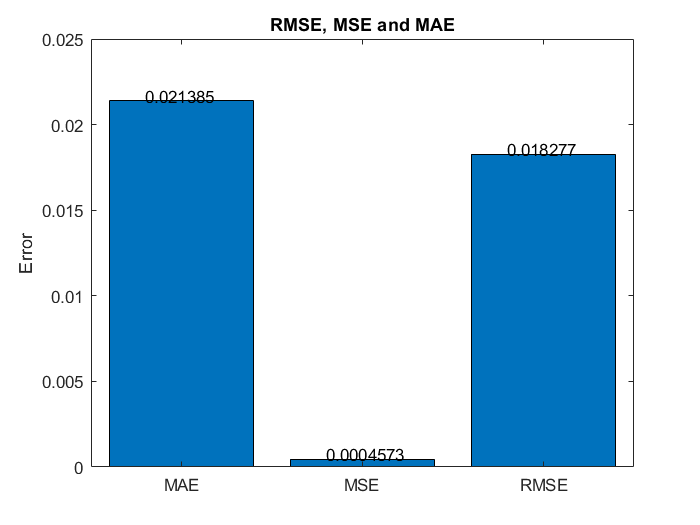

[rmse_month,mse_month,mae_month]=fBar_RmseMseMae(estimate_month,output_month);

save(fullfile(datapath,'rmse_month.mat'),'rmse_month');
save(fullfile(datapath,'mse_month.mat'),'mse_month');
save(fullfile(datapath,'mae_month.mat'),'mae_month');

%figure; plot([estimate_month,output_month]);xlabel('samples');ylabel('value');
%legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
%title('Active Energy (KWh) with 1 month of prediction');
clear model_month output_month estimate_month rmse_month mse_month mae_month RMSE_month

# RMSE (Testing): 1 week [threshold = 0.750;training_size=0.85;]

% input: Energy
input_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size):size(NewDataFeatures,1)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size)+1:size(NewDataFeatures,1)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
%[model_week, RMSE_week] = trainRegressionModel_week(input_train, output_train);
[model_week, RMSE_week] = trainRegressionModel_week_filtered(input_train, output_train);
RMSE_week

RMSE_week = 0.2358

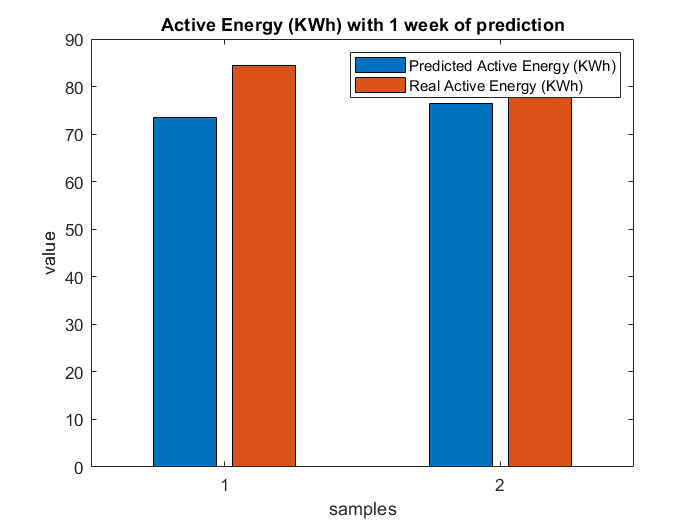

estimate_week=model_week.predictFcn(input_val);
estimate_week=fDenormalize(estimate_week,AEds.max,AEds.min);
output_week=fDenormalize(output_val,AEds.max,AEds.min);
figure; bar([estimate_week,output_week]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 week of prediction');

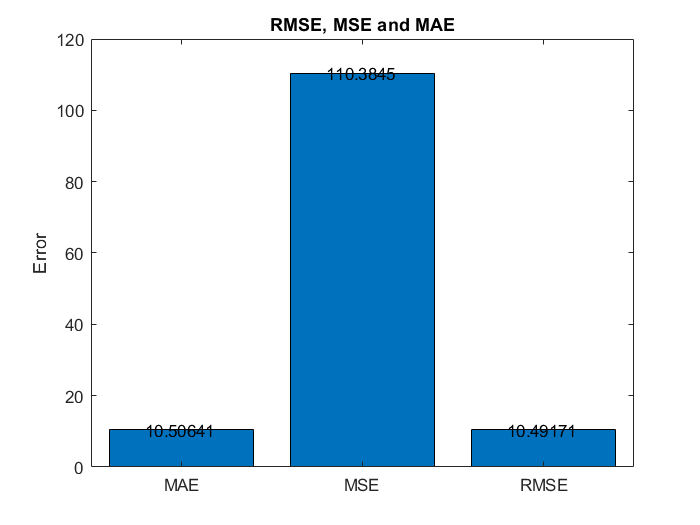

rmse_week = 10.5064

mse_week = 110.3845

mae_week = 10.4917

[rmse_week,mse_week,mae_week]=fBar_RmseMseMae(estimate_week,output_week)

RMSE_day = 0.0535

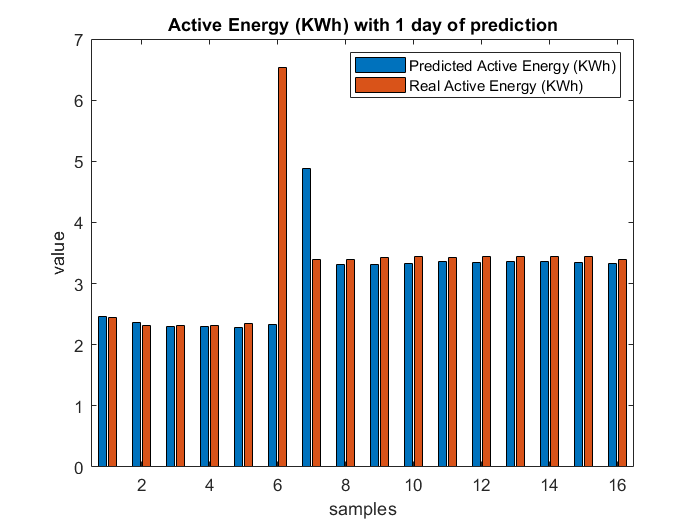

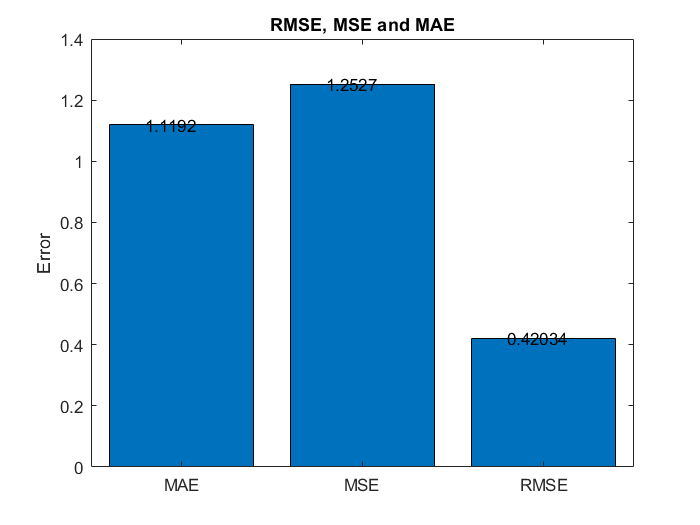

RMSE_hour = 0.0232

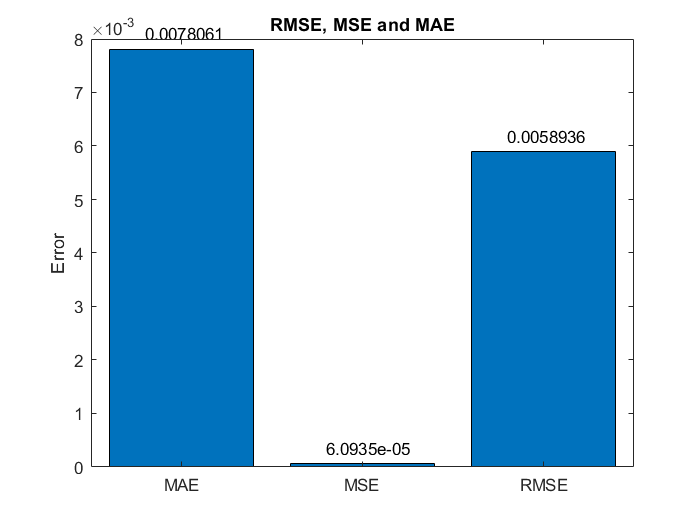

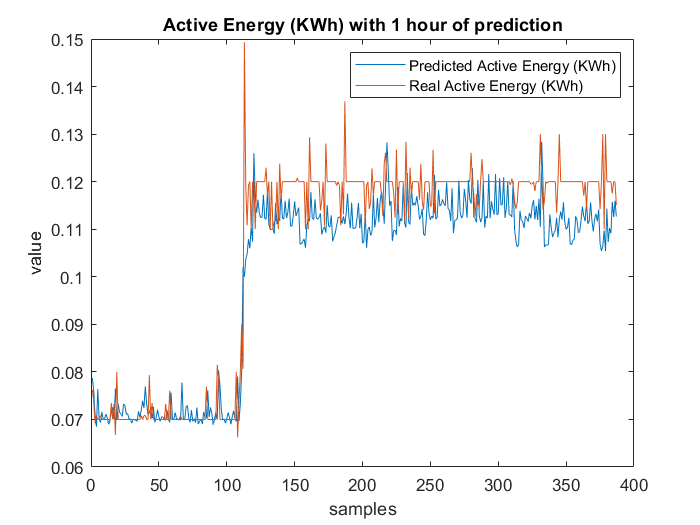

RMSE_minute = 0.0305

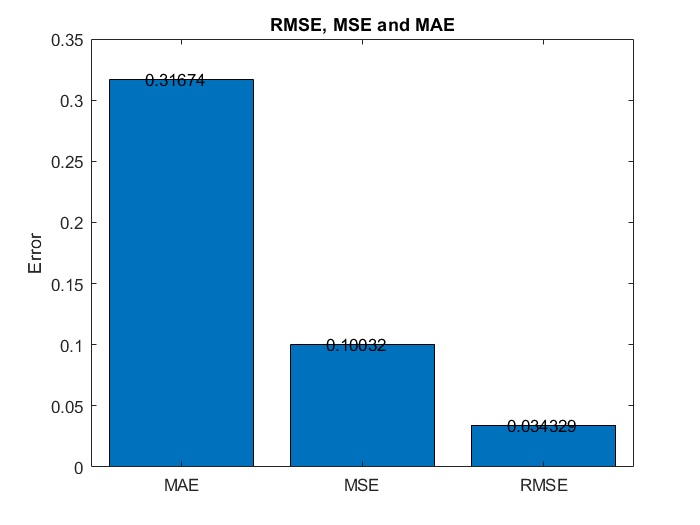

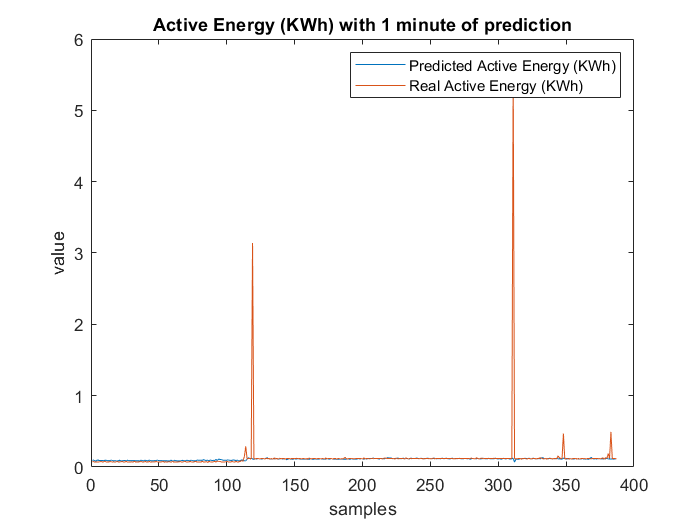

save(fullfile(datapath,'rmse_week.mat'),'rmse_week');
save(fullfile(datapath,'mse_week.mat'),'mse_week');
save(fullfile(datapath,'mae_week.mat'),'mae_week');

%figure; plot([estimate_week,output_week]);xlabel('samples');ylabel('value');
%legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
%title('Active Energy (KWh) with 1 week of prediction');
clear model_week output_week estimate_week rmse_week mse_week mae_week RMSE_week

# Summary RMSE (Testing): Week, Day, Hour and Min [threshold = 0.750;training_size=0.85;]

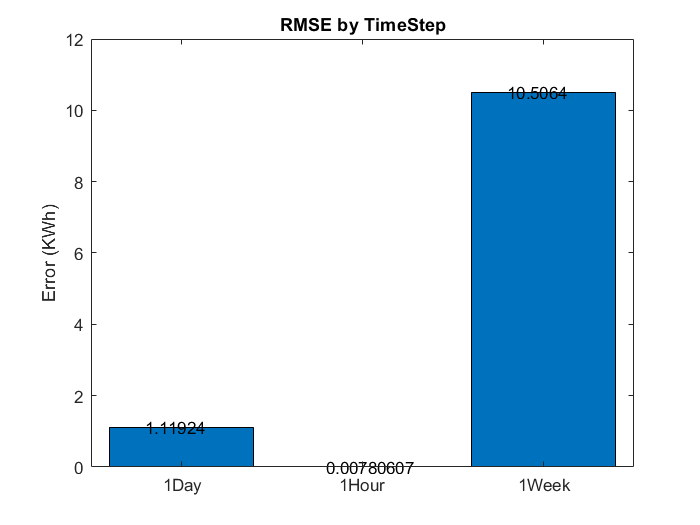

%Month
rmse_month = load(fullfile(datapath,'rmse_month.mat'));rmse_month=rmse_month.rmse_month;
mse_month = load(fullfile(datapath,'mse_month.mat'));mse_month=mse_month.mse_month;
mae_month = load(fullfile(datapath,'mae_month.mat'));mae_month=mae_month.mae_month;
%Week
rmse_week = load(fullfile(datapath,'rmse_week.mat'));rmse_week=rmse_week.rmse_week;
mse_week = load(fullfile(datapath,'mse_week.mat'));mse_week=mse_week.mse_week;
mae_week = load(fullfile(datapath,'mae_week.mat'));mae_week=mae_week.mae_week;
%Day
rmse_day = load(fullfile(datapath,'rmse_day.mat'));rmse_day=rmse_day.rmse_day;
mse_day = load(fullfile(datapath,'mse_day.mat'));mse_day=mse_day.mse_day;
mae_day = load(fullfile(datapath,'mae_day.mat'));mae_day=mae_day.mae_day;
%Hour
rmse_hour = load(fullfile(datapath,'rmse_hour.mat'));rmse_hour=rmse_hour.rmse_hour;
mse_hour = load(fullfile(datapath,'mse_hour.mat'));mse_hour=mse_hour.mse_hour;
mae_hour = load(fullfile(datapath,'mae_hour.mat'));mae_hour=mae_hour.mae_hour;
%Minute
rmse_minute = load(fullfile(datapath,'rmse_minute.mat'));rmse_minute=rmse_minute.rmse_minute;
mse_minute = load(fullfile(datapath,'mse_minute.mat'));mse_minute=mse_minute.mse_minute;
mae_minute = load(fullfile(datapath,'mae_minute.mat'));mae_minute=mae_minute.mae_minute;

%c = categorical({'1Month','1Week','1Day','1Hour','1Min'});
%values = [rmse_month rmse_week rmse_day rmse_hour rmse_minute];%rmse
c = categorical({'1Week','1Day','1Hour'});
values = [rmse_week rmse_day rmse_hour];%rmse
figure;
b=bar(c,values);
ylabel('Error (KWh)')
title('RMSE by TimeStep')
xtips1 = b(1).XEndPoints - 0.2;
ytips1 = b(1).YEndPoints + 0.0003;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

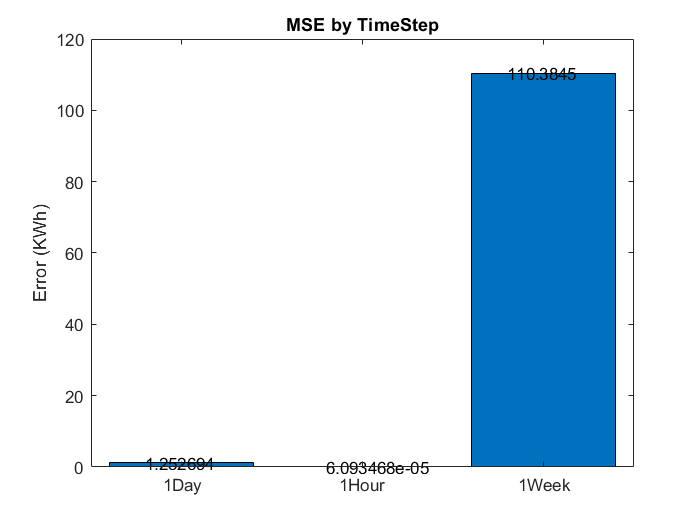

%values = [mse_month mse_week mse_day mse_hour mse_minute];%mse
values = [mse_week mse_day mse_hour];%mse
figure;
b=bar(c,values);
ylabel('Error (KWh)')
title('MSE by TimeStep')
xtips1 = b(1).XEndPoints - 0.2;
ytips1 = b(1).YEndPoints + 0.0003;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

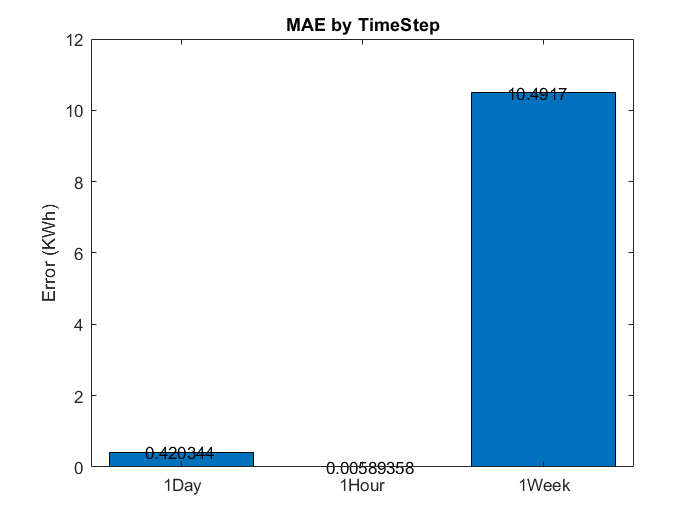

%values = [mae_month mae_week mae_day mae_hour mae_minute];%1-R2
values = [mae_week mae_day mae_hour];%1-R2
figure;
b=bar(c,values);
ylabel('Error (KWh)')
title('MAE by TimeStep')
xtips1 = b(1).XEndPoints - 0.2;
ytips1 = b(1).YEndPoints + 0.0003;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

# FutureWork

%Continue to record more data on more workstations.
%Create a model for estimating memory and CPU consumption since there are spaces without these values.
%Make a real time consumption prediction system.